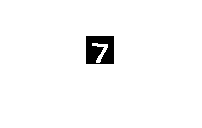

imshow(imageTest(:,:,1))

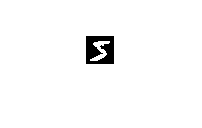

imshow(imageTrain(:,:,1))

image=imageTest(:,:,1)-imageTrain(:,:,1)

image =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0    -3   -18   -18   -18  -126  -136  -175   -26  -166  -255  -247  -127   

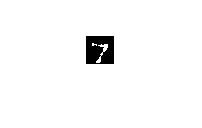

imshow(image)

norm(image)

ans = 1.3563e+03

testImg=imageTest(:,:,1);
Euc_dist=zeros(1,30);
for i =1:30
    trainImg=imageTrain(:,:,i);
    Euc_dist(i)=norm(testImg-trainImg);
    [minDist,minIndex]=min(Euc_dist)
end